clear all;
L=1.516;
t0=0;
t_final=4;
Ts=0.1

Ts = 0.1000

t_list=(t0:Ts:t_final)'

t_list =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


max_steering_deg_speed=5

max_steering_deg_speed = 5

max_steering_rad_speed=5*3.14/180

max_steering_rad_speed = 0.0872

u_angle_use=[-15;-12.5;-10;-7.5;-5;-2.5;0;2.5;5;7.5;10;12.5;15]

u_angle_use =   -15.0000
  -12.5000
  -10.0000
   -7.5000
   -5.0000
   -2.5000
         0
    2.5000
    5.0000
    7.5000


u_angle_list_15l=repmat(degree2rad(u_angle_use(1)),size(t_list,1),1);
speedup_length=floor(abs(degree2rad(u_angle_use(1)))/max_steering_rad_speed/Ts)

speedup_length = 30

u_angle_list_15l(1:speedup_length)=linspace(0,degree2rad(u_angle_use(1)),speedup_length)

u_angle_list_15l =          0
   -0.0090
   -0.0181
   -0.0271
   -0.0361
   -0.0451
   -0.0542
   -0.0632
   -0.0722
   -0.0812



u_angle_list_15r=repmat(degree2rad(u_angle_use(end)),size(t_list,1),1);
u_angle_list_12_5l=repmat(degree2rad(u_angle_use(2)),size(t_list,1),1);
u_angle_list_12_5r=repmat(degree2rad(u_angle_use(end-1)),size(t_list,1),1);
u_angle_list_10l=repmat(degree2rad(u_angle_use(3)),size(t_list,1),1);
u_angle_list_10r=repmat(degree2rad(u_angle_use(end-2)),size(t_list,1),1);
u_angle_list_7_5l=repmat(degree2rad(u_angle_use(4)),size(t_list,1),1);
u_angle_list_7_5r=repmat(degree2rad(u_angle_use(end-3)),size(t_list,1),1);
u_angle_list_5l=repmat(degree2rad(u_angle_use(5)),size(t_list,1),1);
u_angle_list_5r=repmat(degree2rad(u_angle_use(end-4)),size(t_list,1),1);
u_angle_list_2_5l=repmat(degree2rad(u_angle_use(6)),size(t_list,1),1);
u_angle_list_2_5r=repmat(degree2rad(u_angle_use(end-5)),size(t_list,1),1);
u_angle_list_0=repmat(degree2rad(u_angle_use(7)),size(t_list,1),1);
cof_engin=0.27;
u_engin_use=[0;1;2]%burn mode

u_engin_use =      0
     1
     2



u_engin_list_fast=repmat(u_engin_use(3)*cof_engin,size(t_list,1),1);
u_engin_list_slow=repmat(u_engin_use(2)*cof_engin,size(t_list,1),1);
u_engin_list_close=repmat(u_engin_use(1)*cof_engin,size(t_list,1),1);
cof_break=-0.2778;
u_break_use=(0:1:34)'

u_break_use =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


u_break_list=repmat(u_break_use(1)*cof_break,size(t_list,1),1);
x_list=zeros(4,0)


x_list =

  空的 4×0 double 矩阵




x0=0;
y0=0;
theta0=0;
v0=0;
s0=[x0;y0;theta0;v0];

ans = 30

bag= rosbag('london_track_demo1.bag');
WaypointTopic= select(bag, 'Topic', '/sim/track');
WaypointMsg = readMessages(WaypointTopic,'DataFormat','struct');

path_x=[];
path_y=[];

for i= 1:length(WaypointMsg)
    path_x= [path_x, WaypointMsg{i,1}.Points.X];
    path_y= [path_y, WaypointMsg{i,1}.Points.Y];
end

path_edge= [path_x' path_y'];
%csvwrite('road_data_Cplus.csv',path_edge)
%path_center= xlsread("london_track.xlsx");

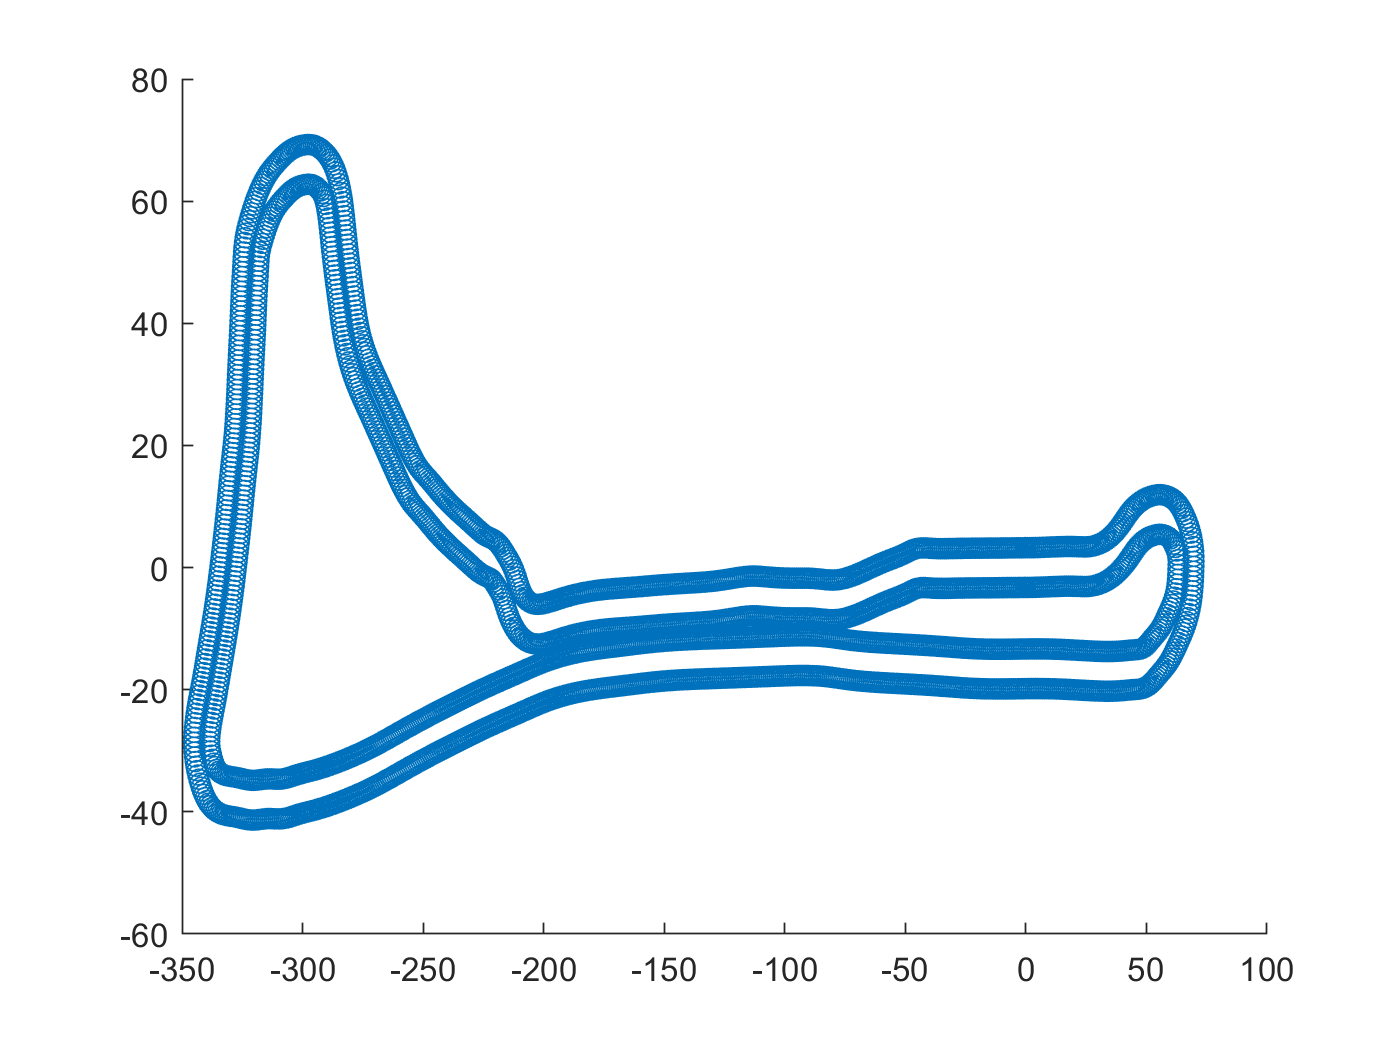

close all;
figure;
scatter(path_x, path_y);

% scatter(center_x,center_y);
%hold on;
%scatter(path_center(:,1), path_center(:,2));
%hold off

s0 =     0.2430
         0
         0
    0.5400


s0 =     1.0260
         0
         0
    1.0800


s0 =     2.3490
         0
         0
    1.6200


s0 =     4.2120
         0
         0
    2.1600


s0 =     6.6150
         0
         0
    2.7000


s0 =     9.5580
         0
         0
    3.2400


s0 =    13.0410
         0
         0
    3.7800


s0 =    17.0640
         0
         0
    4.3200


s0 =    21.6270
         0
         0
    4.8600


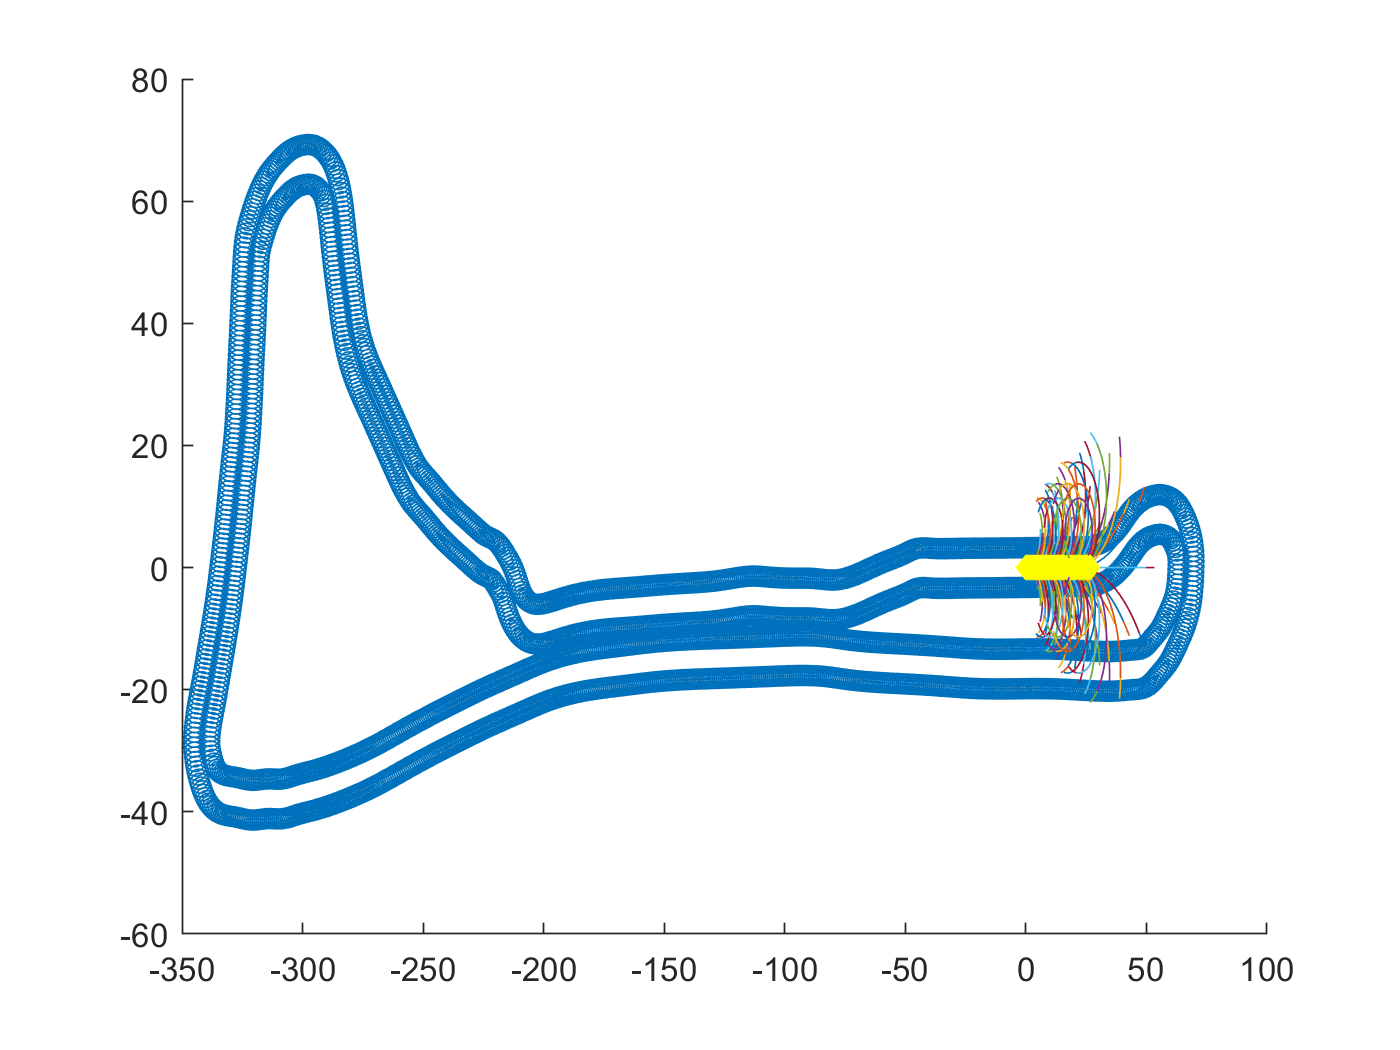

s0 =    26.7300
         0
         0
    5.4000


for i=1:10
    x_list_e0_f=ode_traj(s0,t_list,Ts,u_angle_list_0,u_engin_list_fast,u_break_list);
    x_list_e2_5l_f=ode_traj(s0,t_list,Ts,u_angle_list_2_5l,u_engin_list_fast,u_break_list);
    x_list_e2_5r_f=ode_traj(s0,t_list,Ts,u_angle_list_2_5r,u_engin_list_fast,u_break_list);
    x_list_e5l_f=ode_traj(s0,t_list,Ts,u_angle_list_5l,u_engin_list_fast,u_break_list);
    x_list_e5r_f=ode_traj(s0,t_list,Ts,u_angle_list_5r,u_engin_list_fast,u_break_list);
    x_list_e7_5l_f=ode_traj(s0,t_list,Ts,u_angle_list_7_5l,u_engin_list_fast,u_break_list);
    x_list_e7_5r_f=ode_traj(s0,t_list,Ts,u_angle_list_7_5r,u_engin_list_fast,u_break_list);
    x_list_e10l_f=ode_traj(s0,t_list,Ts,u_angle_list_10l,u_engin_list_fast,u_break_list);
    x_list_e10r_f=ode_traj(s0,t_list,Ts,u_angle_list_10r,u_engin_list_fast,u_break_list);
    x_list_e12_5l_f=ode_traj(s0,t_list,Ts,u_angle_list_12_5l,u_engin_list_fast,u_break_list);
    x_list_e12_5r_f=ode_traj(s0,t_list,Ts,u_angle_list_12_5r,u_engin_list_fast,u_break_list);
    x_list_e15l_f=ode_traj(s0,t_list,Ts,u_angle_list_15l,u_engin_list_fast,u_break_list);
    x_list_e15r_f=ode_traj(s0,t_list,Ts,u_angle_list_15r,u_engin_list_fast,u_break_list);

    x_list_e0_s=ode_traj(s0,t_list,Ts,u_angle_list_0,u_engin_list_slow,u_break_list);
    x_list_e2_5l_s=ode_traj(s0,t_list,Ts,u_angle_list_2_5l,u_engin_list_slow,u_break_list);
    x_list_e2_5r_s=ode_traj(s0,t_list,Ts,u_angle_list_2_5r,u_engin_list_slow,u_break_list);
    x_list_e5l_s=ode_traj(s0,t_list,Ts,u_angle_list_5l,u_engin_list_slow,u_break_list);
    x_list_e5r_s=ode_traj(s0,t_list,Ts,u_angle_list_5r,u_engin_list_slow,u_break_list);
    x_list_e7_5l_s=ode_traj(s0,t_list,Ts,u_angle_list_7_5l,u_engin_list_slow,u_break_list);
    x_list_e7_5r_s=ode_traj(s0,t_list,Ts,u_angle_list_7_5r,u_engin_list_slow,u_break_list);
    x_list_e10l_s=ode_traj(s0,t_list,Ts,u_angle_list_10l,u_engin_list_slow,u_break_list);
    x_list_e10r_s=ode_traj(s0,t_list,Ts,u_angle_list_10r,u_engin_list_slow,u_break_list);
    x_list_e12_5l_s=ode_traj(s0,t_list,Ts,u_angle_list_12_5l,u_engin_list_slow,u_break_list);
    x_list_e12_5r_s=ode_traj(s0,t_list,Ts,u_angle_list_12_5r,u_engin_list_slow,u_break_list);
    x_list_e15l_s=ode_traj(s0,t_list,Ts,u_angle_list_15l,u_engin_list_slow,u_break_list);
    x_list_e15r_s=ode_traj(s0,t_list,Ts,u_angle_list_15r,u_engin_list_slow,u_break_list);
    hold on
    plot(x_list_e0_f(1,:),x_list_e0_f(2,:),...
    x_list_e2_5l_f(1,:),x_list_e2_5l_f(2,:),...
    x_list_e2_5r_f(1,:),x_list_e2_5r_f(2,:),...
    x_list_e5l_f(1,:),x_list_e5l_f(2,:),...
    x_list_e5r_f(1,:),x_list_e5r_f(2,:),...
    x_list_e7_5l_f(1,:),x_list_e7_5l_f(2,:),...
    x_list_e7_5r_f(1,:),x_list_e7_5r_f(2,:),...
    x_list_e10l_f(1,:),x_list_e10l_f(2,:),...
    x_list_e10r_f(1,:),x_list_e10r_f(2,:),...
    x_list_e12_5l_f(1,:),x_list_e12_5l_f(2,:),...
    x_list_e12_5r_f(1,:),x_list_e12_5r_f(2,:),...
    x_list_e15l_f(1,:),x_list_e15l_f(2,:),...
    x_list_e15r_f(1,:),x_list_e15r_f(2,:),...
    x_list_e0_s(1,:),x_list_e0_s(2,:),...
    x_list_e2_5l_s(1,:),x_list_e2_5l_s(2,:),...
    x_list_e2_5r_s(1,:),x_list_e2_5r_s(2,:),...
    x_list_e5l_s(1,:),x_list_e5l_s(2,:),...
    x_list_e5r_s(1,:),x_list_e5r_s(2,:),...
    x_list_e7_5l_s(1,:),x_list_e7_5l_s(2,:),...
    x_list_e7_5r_s(1,:),x_list_e7_5r_s(2,:),...
    x_list_e10l_s(1,:),x_list_e10l_s(2,:),...
    x_list_e10r_s(1,:),x_list_e10r_s(2,:),...
    x_list_e12_5l_s(1,:),x_list_e12_5l_s(2,:),...
    x_list_e12_5r_s(1,:),x_list_e12_5r_s(2,:),...
    x_list_e15l_s(1,:),x_list_e15l_s(2,:),...
    x_list_e15r_s(1,:),x_list_e15r_s(2,:))
    scatter(x_list_e0_f(1,1:10),x_list_e0_f(2,1:10),"yellow","filled","d","linewidth",1.5)
    s0=x_list_e0_f(:,10)
end